# Camille Rakotoranto, April 2025, MATLAB R2024b, The MathWorks Inc., Natick, MA, USA

# FOOOF Tuning

This script allows the tuning of the FOOOF algorithm based on the datasets of the study. Particularly, tuning is based on the T7-Oz and T8-Oz configurations, for the Resting State and Alpha Block conditions (Eyes Closed and Eyes Open). Section 1 computes the PSDs for these. Section 2 uses an iterative approach to determine the best parameters for a given datset. Assessment of the fit is quantitative (based on the R^2 and error of fit) and qualitative, as per Donoghue et al. (2020).

**Note: Section 2 requires manual adjustment of the dataset you wish to implement FOOOF to. For more reliable tuning, multiple datasets should be used and the most common best parameter results selected for final implementation.**

## Section 1: Computation of Power Spectral Densities

% Set up an array to hold the PSD data for each channel across num_participants
psd_T7_all_num_participants = [];
psd_T8_all_num_participants = [];

psd_T7ec_all_num_participants = [];
psd_T7eo_all_num_participants = [];
psd_T8ec_all_num_participants = [];
psd_T8eo_all_num_participants = [];

f_T7_all = [];
f_T8_all = [];
f_T7_ec_all = [];
f_T7_eo_all = [];
f_T8_ec_all = [];
f_T8_eo_all = [];


% Sampling Frequency and Parameters for pwelch
Fs = 250;                           % Sampling frequency (Hz)
window_length = 2 * Fs;             % Window length of 2 seconds
nfft = 2^nextpow2(window_length);   % Use the next power of 2 for NFFT
noverlap = window_length / 2;       % 50% overlap

num_participants = 1; % change as needed

% Loop through each participant
for participant = 1:num_participants

    % Load Resting State dat
    filename = sprintf('Participant_%d_T7andT8_refPOz_RS.mat', participant); 
    loaded_data = load(filename);
    
    % Extract Restng state 
    data_T7 = loaded_data.participant_data.channel_T7; 
    data_T8 = loaded_data.participant_data.channel_T8; 

    filename = sprintf('Participant_%d_T7andT8_refPOz_AB.mat', participant); 
    loaded_data = load(filename);
    % Extract Eyes Open and Eyes Closed
    data_T7_ec = loaded_data.participant_data.channel_T7ec; 
    data_T7_eo = loaded_data.participant_data.channel_T7eo; 
    data_T8_ec = loaded_data.participant_data.channel_T8ec; 
    data_T8_eo = loaded_data.participant_data.channel_T8eo;
    
    % Compute PSDs
    [psd_T7, f_T7] = pwelch(data_T7, window_length, noverlap, nfft, Fs);
    [psd_T8, f_T8] = pwelch(data_T8, window_length, noverlap, nfft, Fs); 

    [psd_T7_ec, f_T7ec] = pwelch(data_T7_ec, window_length, noverlap, nfft, Fs); 
    [psd_T7_eo, f_T7eo] = pwelch(data_T7_eo, window_length, noverlap, nfft, Fs); 
    [psd_T8_ec, f_T8ec] = pwelch(data_T8_ec, window_length, noverlap, nfft, Fs); 
    [psd_T8_eo, f_T8eo] = pwelch(data_T8_eo, window_length, noverlap, nfft, Fs);

    % Store the PSD data for participant
    psd_T7_all_num_participants = [psd_T7_all_num_participants, psd_T7];
    psd_T8_all_num_participants = [psd_T8_all_num_participants, psd_T8];

    psd_T7ec_all_num_participants = [psd_T7ec_all_num_participants, psd_T7ec];
    psd_T7eo_all_num_participants = [psd_T7eo_all_num_participants, psd_T7eo];
    psd_T8ec_all_num_participants = [psd_T8ec_all_num_participants, psd_T8ec];
    psd_T8eo_all_num_participants = [psd_T8eo_all_num_participants, psd_T8eo];

    f_T7_all = [f_T7_all, f_T7];
    f_T8_all = [f_T8_all, f_T8];
    f_T7_ec_all = [f_T7_ec_all, f_T7ec];
    f_T7_eo_all = [f_T7_eo_all, f_T7eo];
    f_T8_ec_all = [f_T8_ec_all, f_T8ec];
    f_T8_eo_all = [f_T8_eo_all, f_T8eo];
   
end


## Section 2: Finding the best parameters for FOOOF

This section applies FOOOF the PSD chosen - not this choice must be manually changed. Comparing the results of multiple PSDs allows the election of the best parameters. 


% Use the NumPy to access FOOOF in MATLAB (Python extension)
np = py.importlib.import_module('numpy');

% Define frequency range (ensure proper list format for Python)
f_range = [2, 100];
freq_range = py.list([2, 100]);

% Select the dataset to look at
% the source needs to be changed based on the dataet you test
participant = 1; % change as required
psd_case = psd_T7_all_num_participants(:, participant); % change as required
f_case = f_T7_all(:, participant); % change as required

% Convert MATLAB arrays to NumPy arrays
f_test = np.array(f_case); 
psd_test = np.array(psd_case); 

% Initialise arrays and struct to store the best values
best_r2 = -inf;
best_error = inf;
best_params = struct();

%% Define arrays to find optimal parameter values
% Width of peaks
peak_width_limits_options = {[1.1, 4], [1.3, 4], [1.5, 4], [1.7, 4], [1.9, 4], [2.1, 4], [2.3, 4], [2.5, 4], [1.1, 6], [1.3, 6], [1.5, 6], [1.7, 6], [1.9, 6], [2.1, 6], [2.3, 6], [2.5, 6], [2.7, 6], [2.9, 6], [3.1, 6], [3.3, 6], [3.5, 6], [1.1, 7], [1.3, 7], [1.5, 7], [1.7, 7], [1.9, 7], [2.1, 7], [2.3, 7], [2.5, 7], [2.7, 7], [2.9, 7], [3.1, 7], [3.3, 7], [3.5, 7], [1.1 8], [1.3, 8], [1.5, 8], [1.7, 8], [1.9, 8], [2.1, 8], [2.3, 8], [2.5, 8], [2.7, 8], [2.9, 8], [3.1, 8], [3.3, 8], [3.5, 8], [1.1, 9], [1.3, 9], [1.5, 9], [1.7, 9], [1.9, 9], [2.1, 9], [2.3, 9], [2.5, 9], [2.7, 9], [2.9, 9], [3.1, 9], [3.3, 9], [3.5, 9], [1.1, 10], [1.3, 10], [1.5, 10], [1.7, 10], [1.9, 10], [2.1, 10], [2.3, 10], [2.5, 10], [2.7, 10], [2.9, 10], [3.1, 10], [3.3, 10], [3.5, 10], [1.1, 11], [1.3, 11], [1.5, 11], [1.7, 11], [1.9, 11], [2.1, 11], [2.3, 11], [2.5, 11], [2.7, 11], [2.9, 11], [3.1, 11], [3.3, 11], [3.5, 11], [1.1, 12], [1.3, 12], [1.5, 12], [1.7, 12], [1.9, 12], [2.1, 12], [2.3, 12], [2.5, 12], [2.7, 12], [2.9, 12], [3.1, 12], [3.3, 12], [3.5, 12]};
% Maximum number of peaks
max_n_peaks_options = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12];
% Minimum height of peak detected
min_peak_height_options = [0.05, 0.01, 0.015, 0.02, 0.025, 0.03, 0.035, 0.04, 0.045, 0.5, 0.6, 0.7, 0.8, 0.9, 1, 2, 3, 4, 5, 6];
% Peak threshold for detection
peak_threshold_options = [1.5, 1.6, 1.7, 1.75, 1.8, 1.9, 2.0, 2.1, 2.2, 2.25, 2.3, 2.4 2.5, 2.6, 2.7, 2.75, 2.8, 2.9 3.0];

% Loop through all parameter combinations for one dataset
for i = 1:length(peak_width_limits_options)
    for j = 1:length(max_n_peaks_options)
        for k = 1:length(min_peak_height_options)
            for l = 1:length(peak_threshold_options)
                
                % Use the current parameter values
                peak_width_limits = py.tuple(peak_width_limits_options{i});
                max_n_peaks = max_n_peaks_options(j);
                min_peak_height = min_peak_height_options(k);
                peak_threshold = peak_threshold_options(l);

                % Implement FOOOF using parameter values
                fooof_model = py.fooof.FOOOF(pyargs( ...
                    'peak_width_limits', peak_width_limits, ...
                    'max_n_peaks', max_n_peaks, ...
                    'min_peak_height', min_peak_height, ...
                    'peak_threshold', peak_threshold, ...
                    'aperiodic_mode', 'knee'));  

                % Obtain the quality of the fit
                fooof_model.fit(f_test, psd_test, freq_range);
                r2 = fooof_model.get_params('r_squared');
                error = fooof_model.get_params('error');

                % Check if it's the best model as up to now
                if r2 > best_r2 && error < best_error
                    best_r2 = r2;
                    best_error = error;
                    best_params.peak_width_limits = peak_width_limits_options{i};
                    best_params.max_n_peaks = max_n_peaks;
                    best_params.min_peak_height = min_peak_height;
                    best_params.peak_threshold = peak_threshold;
                    best_model = fooof_model;
                end
            end
        end
    end
end


% Print best parameters found this dataset
disp('Best Parameters:');

Best Parameters:


disp(best_params);

    peak_width_limits: [1.1000 4]
          max_n_peaks: 1
      min_peak_height: 0.0900
       peak_threshold: 2.1000



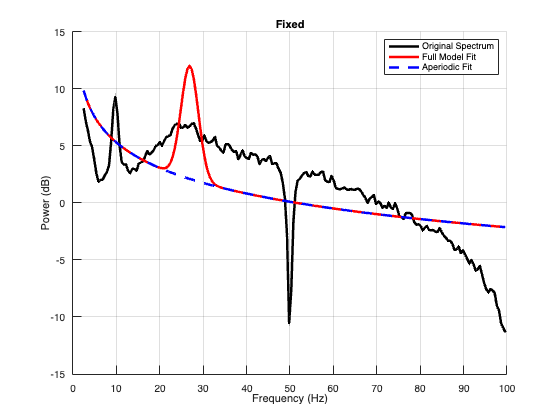


% Plot the pre- and post-FOOOF PSDs for qualitative assessment
settings = struct();
% set the range
f_range = [2, 100];
settings = fooof_check_settings(settings);
% Adjust the parameter values
settings.peak_width_limits = best_params.peak_width_limits;
settings.max_n_peaks = best_params.max_n_peaks;
settings.min_peak_height = best_params.min_peak_height;
settings.peak_threshold = best_params.peak_threshold;
settings.verbose = false; 

% Plot the 'fixed' aperiodic mode 
settings.aperiodic_mode = 'fixed';  
fooof_results_fixed = fooof(f_case, psd_case, f_range, settings, true);
fooof_results_fixed = fooof_db(fooof_results_fixed);

fooof_plot(fooof_results_fixed);
title('Fixed');   

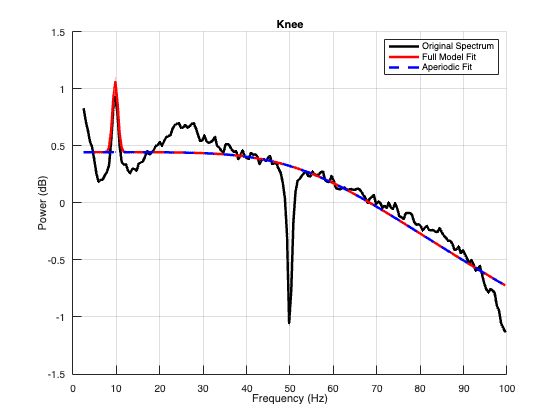


% Plot the 'knee' aperiodic mode 
settings.aperiodic_mode = 'knee';  
fooof_results_knee = fooof(f_case, psd_case, f_range, settings, true);
fooof_results_knee = fooof_db(fooof_results_knee);

fooof_plot(fooof_results_knee);
title('Knee');